# Updatted Glenoid Processing Tests using GIBBON

## Starting Notes

This script is an adaptation of the original (so is very similar), but only takes the aspects that were found to be the most appropriate from the original.

This code uses the right scapula and humerus extracted from the Visible Human CT dataset to trial processing steps for FE analysis with a focus on using the GIBBON toolbox. The scapula and humerus meshes were exported from the Materialise suite of software as ASCII STL's in their original coordinate system (scapula.stl and humerus.stl). The only processing performed on these meshes was to uniformly mesh them to have a target triangle edge length of 1mm. The scapula was also smoothed (smoothScapula.stl) with a 0.7 factor in 3matic. The glenoidSurface.stl was achieved by marking an approximation of the surface, smoothing the edge of this and then extracting this surface from the scapula part. The meshes still aren't necessraily too smooth and could do with some extra processing or better masking.

There are also a number of additional objects exported that fit these meshes:

- **deepGlenoidCentre.txt:** includes the 3D coordinate of the estimated deepest point at the centre of the glenoid. This should serve as the origin for the scapula coordinate system.

- **glenoidPlanes.xml:** contains the planes fitted around the glenoid surface and glenoid axes. These planes represent the XY, XZ and YZ planes of the glenoid surface, with: (i) the Z axes being the normal away from a plane fitted to the glenoid surface; (ii) the Y axes being parralel to a line made by the supraglenoid and infraglenoid tubercle; and (iii) the X axes being the cross product of these remaining axes, respresenting the anterior-posterio aspect of the glenoid.

- **glenoidRimPoints.txt:** includes the 3D coordinates of a number of points estimated to fall on the glenoid rim. These are mainly estimated from the coronal plane slices of the CT, whereby the closest points/edges to the humerus are selected. They may not fit exactly on the glenoid mesh due to the potential small amount of smoothing done in uniformly remeshing.

- **humeralHeadSphere.txt:** includes the 3D coordinates of the centre and the radius measurement of a sphere fitted to the humeral head mesh.

This code includes a focus on generating cartilage on the surfaces of these structures, using slicing and extending features recently added to GIBBON toolbox, as per the Github issues #62 ([https://github.com/gibbonCode/GIBBON/issues/62](https://github.com/gibbonCode/GIBBON/issues/62)) and #63 ([https://github.com/gibbonCode/GIBBON/issues/63](https://github.com/gibbonCode/GIBBON/issues/63)).

Settings for script

warning off
fontSize = 25;

## Import STL's

Load and visualise STL files

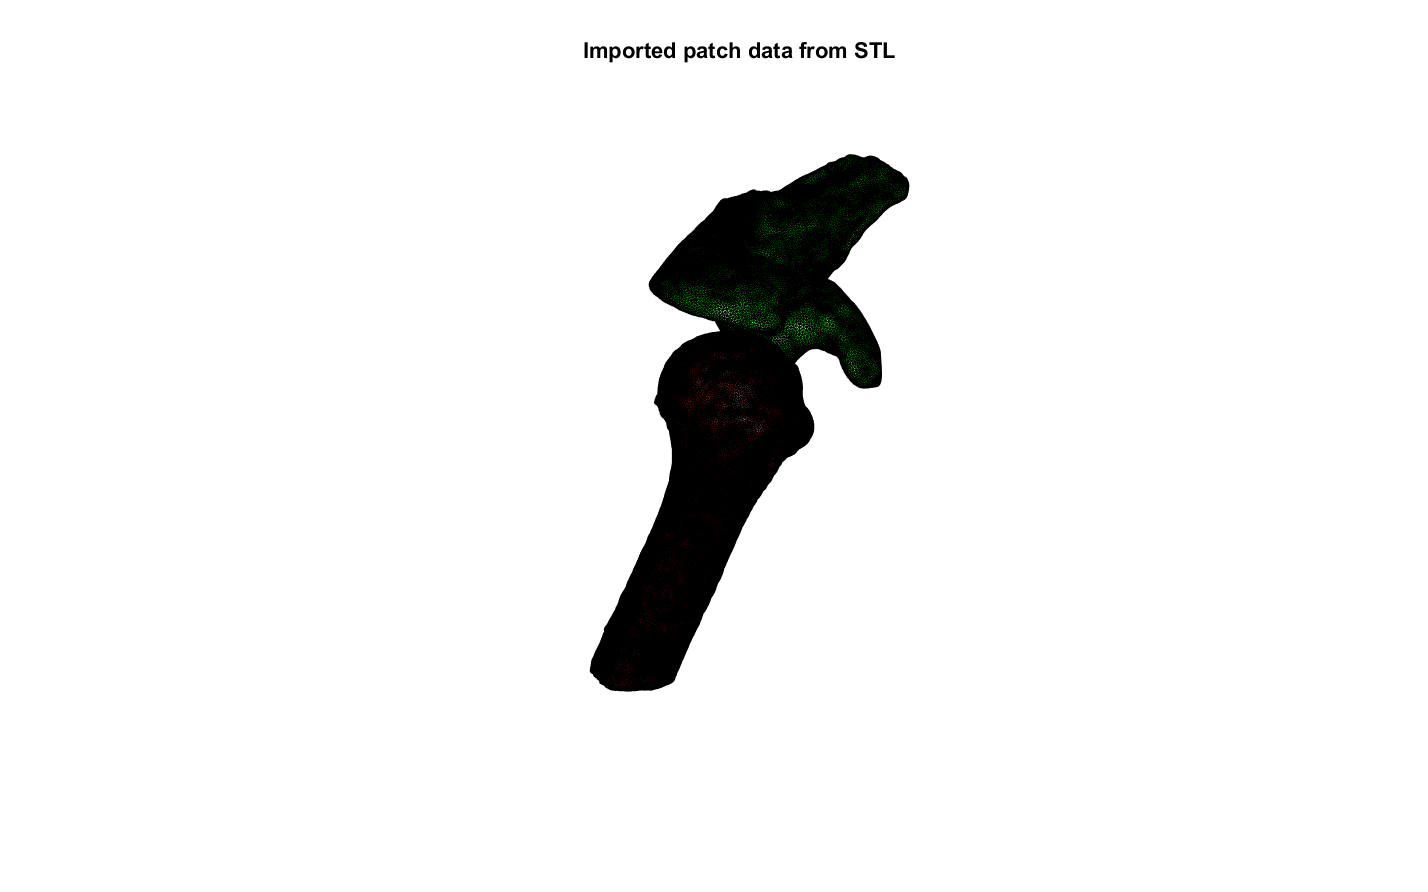

%Load STLs
scapulaSTL = import_STL('smoothScapula.stl');
humerusSTL = import_STL('humerus.stl');
surfaceSTL = import_STL('glenoidSurface.stl');

%Extract the faces and vertices
scapulaF = scapulaSTL.solidFaces{1};
scapulaV = scapulaSTL.solidVertices{1};
humerusF = humerusSTL.solidFaces{1};
humerusV = humerusSTL.solidVertices{1};
surfaceF = surfaceSTL.solidFaces{1};
surfaceV = surfaceSTL.solidVertices{1};

%Merge vertices
[scapulaF,scapulaV] = mergeVertices(scapulaF,scapulaV);
[humerusF,humerusV] = mergeVertices(humerusF,humerusV);
[surfaceF,surfaceV] = mergeVertices(surfaceF,surfaceV);

%Plot the models
cFigure;
title('Imported patch data from STL','fontSize',25);
gpatch(scapulaF,scapulaV,'g','k',1,1e-5);
hold on
gpatch(humerusF,humerusV,'r','k',1,1e-5);
axisGeom;
camlight('headlight');
lighting phong; axis off;

## Identify Cartilage Thickness Based on Humeral Head to Glenoid Distance

The following method uses the approach specified by Buchler et al. (2002), whereby he minimum distance between the bony surfaces of the humeral head and scapula is calculated and then halved to specify maximum or a constant thickness cartilage difference. The process here could be sped up by only looking for specific points on each mesh, but in principal what the following code does is measures the distance of each vertice on the humerus to every one on the extracted glenoid surface. The minimum distance of all these can then be found, and theoretically should relate to the minimum distance between the humeral head and glenoid surface (as long as there aren't any other weird close points).

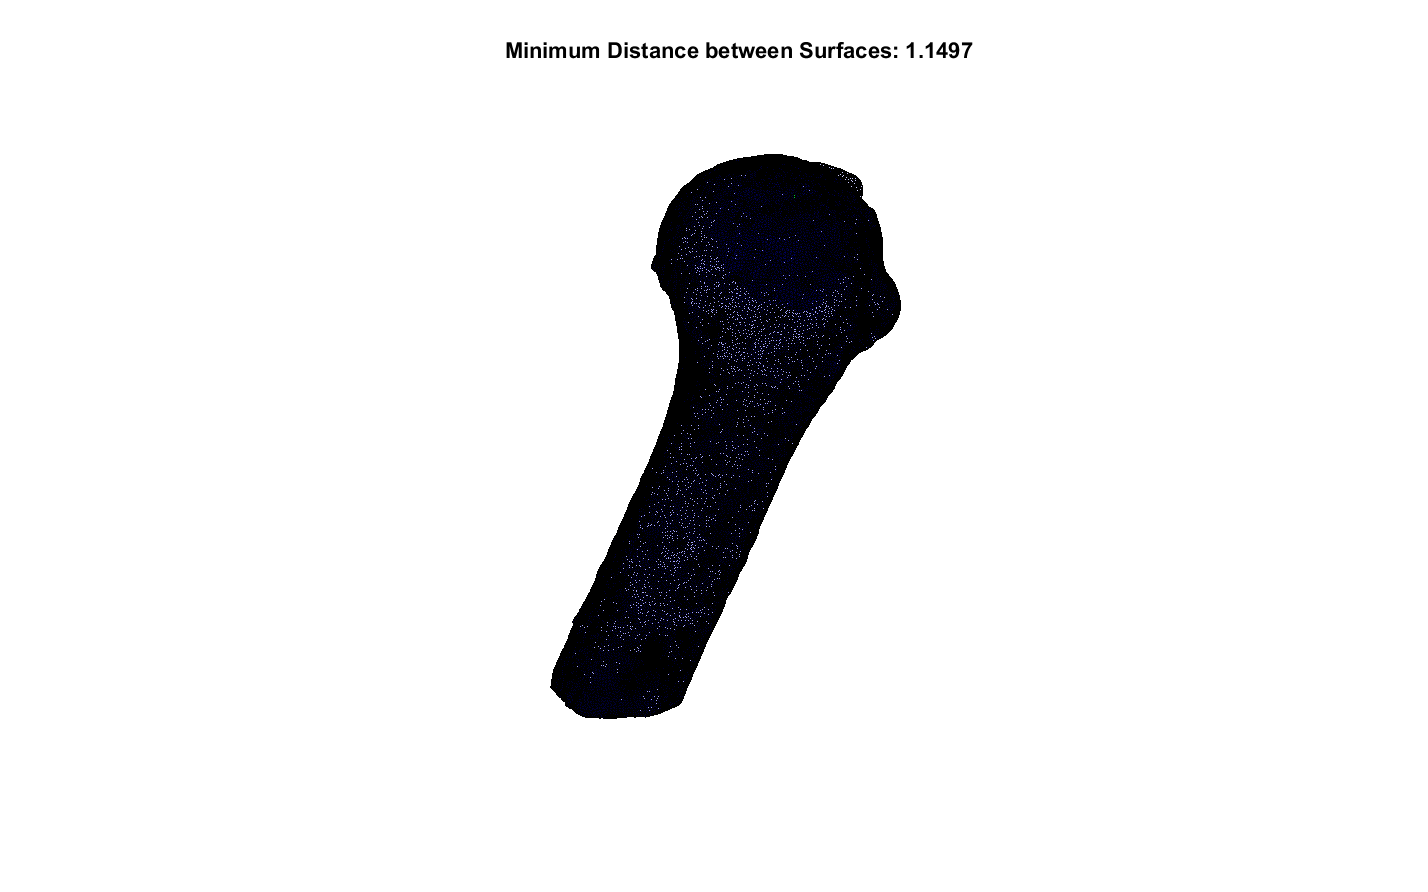

%Set a tremendously large starting minimum distance that will easily be
%minimised by each point
minDist = Inf;

%Loop through the surface points
for ss = 1:length(surfaceV)
    %Get current surface point
    sPt = surfaceV(ss,:);
    %Calculate distance to every humerus point
    currDist = sqrt((humerusV(:,1)-sPt(1)).^2+(humerusV(:,2)-sPt(2)).^2+(humerusV(:,3)-sPt(3)).^2);
    %Get minimum distance
    currMinDist = min(currDist);    
    %Replace min distance if its less than this
    if currMinDist < minDist
        minDist = currMinDist;
        %Set the current min distance points (for visualisation)
        humerusMinPt = humerusV(find(currDist == min(currMinDist),1),:);
        glenoidMinPt = sPt;
    end
    %Cleanup
    clear sPt currDist
end
clear ss

%Visualise the results
cFigure;
title(['Minimum Distance between Surfaces: ',num2str(round(minDist,4))],'fontSize',25);
gpatch(surfaceF,surfaceV,'b','k',0.2,1e-5);
hold on
gpatch(humerusF,humerusV,'b','k',0.2,1e-5);
scatter3(humerusMinPt(:,1),humerusMinPt(:,2),humerusMinPt(:,3),50,'green','filled')
scatter3(glenoidMinPt(:,1),glenoidMinPt(:,2),glenoidMinPt(:,3),50,'red','filled')
axisGeom;
axis off;

%Set maximum cartilage thickness as half of this distance
maxCartilageThickness = minDist/2;

## Import Measurements Data

Import the associated measurements for the scapula and humerus meshes.

%Load the deep glenoid point text
%Read in with line delimiter
C = importdata('deepGlenoidCentre.txt','\n');
%Identify the row with the point label
for rr = 1:length(C)
    rowInd(rr) = contains(C{rr,1},'deepGlenoid');
end
clear rr
%Extract the relevant row
rowTxt = C{rowInd,1};
%Split the string by spaces
rowSplit = strsplit(rowTxt,' ');
%The X,Y,Z coordinates are now in the 2nd, 3rd and 4th cells
landmarks.deepGlenoid(1) = str2double(rowSplit(2));
landmarks.deepGlenoid(2) = str2double(rowSplit(3));
landmarks.deepGlenoid(3) = str2double(rowSplit(4));
%Cleanup
clear C rowInd rowTxt rowSplit

%Load the glenoid rim points
%Read in with line delimiter
C = importdata('glenoidRimPoints.txt','\n');
%Identify the row with the point label
for rr = 1:length(C)
    rowInd(rr) = contains(C{rr,1},'glenoidRim');
end
clear rr
%Extract the relevant row
rowTxt = C(rowInd,1);
%Loop through the number of points
for pp = 1:length(rowTxt)
    %Split the string by spaces
    rowSplit = strsplit(rowTxt{pp},' ');
    %The name is now in the first cell
    %The X,Y,Z coordinates are now in the 2nd, 3rd and 4th cells
    landmarks.(char(rowSplit(1)))(1) = str2double(rowSplit(2));
    landmarks.(char(rowSplit(1)))(2) = str2double(rowSplit(3));
    landmarks.(char(rowSplit(1)))(3) = str2double(rowSplit(4));
    %Create a variable for the glenoid rim names
    glenoidRimLabels{pp} = (char(rowSplit(1)));
end
clear pp
%Cleanup
clear C rowInd rowTxt rowSplit

%Load the humeral head sphere text
%Read in with line delimiter
C = importdata('humeralHeadSphere.txt','\n');
%Identify the row with the point label
for rr = 1:length(C)
    rowInd(rr) = contains(C{rr,1},'humeralHead');
end
clear rr
%Extract the relevant row
rowTxt = C{rowInd,1};
%Split the string by spaces
rowSplit = strsplit(rowTxt,' ');
%The X,Y,Z coordinates are now in the 2nd, 3rd and 4th cells
%The radius size is now in the 5th cell
landmarks.humeralHeadCentre(1) = str2double(rowSplit(2));
landmarks.humeralHeadCentre(2) = str2double(rowSplit(3));
landmarks.humeralHeadCentre(3) = str2double(rowSplit(4));
humeralHeadRadius(1) = str2double(rowSplit(5));
%Cleanup
clear C rowInd rowTxt rowSplit

%Load in the planes xml file
[tree, RootName, DOMnode] = xml_read('glenoidPlanes.xml');
%Extract the details
for pp = 1:3
    planes.(char(tree.Plane(pp).Name)).origin = tree.Plane(pp).Origin;
    planes.(char(tree.Plane(pp).Name)).normal = tree.Plane(pp).Normal;
    planes.(char(tree.Plane(pp).Name)).xAxis = tree.Plane(pp).X_DASH_axis;
    planes.(char(tree.Plane(pp).Name)).yAxis = tree.Plane(pp).Y_DASH_axis;
end
clear pp
%Cleanup
clear tree RootName DOMnode

## Align the Scapula Planes to the World

To make life easier with processing, the XY, YZ and XZ planes of the scapula can be aligned to the world coordinate system, with the origin being at the deep glenoid point. The following code rotates all elements that have been imported so that they all match up.

The following section uses the 'vrrotvec' and 'vrrotvec2mat' functions to align the glenoid coordinate system to the world coordinate system by matching up the world and scapula XY planes.

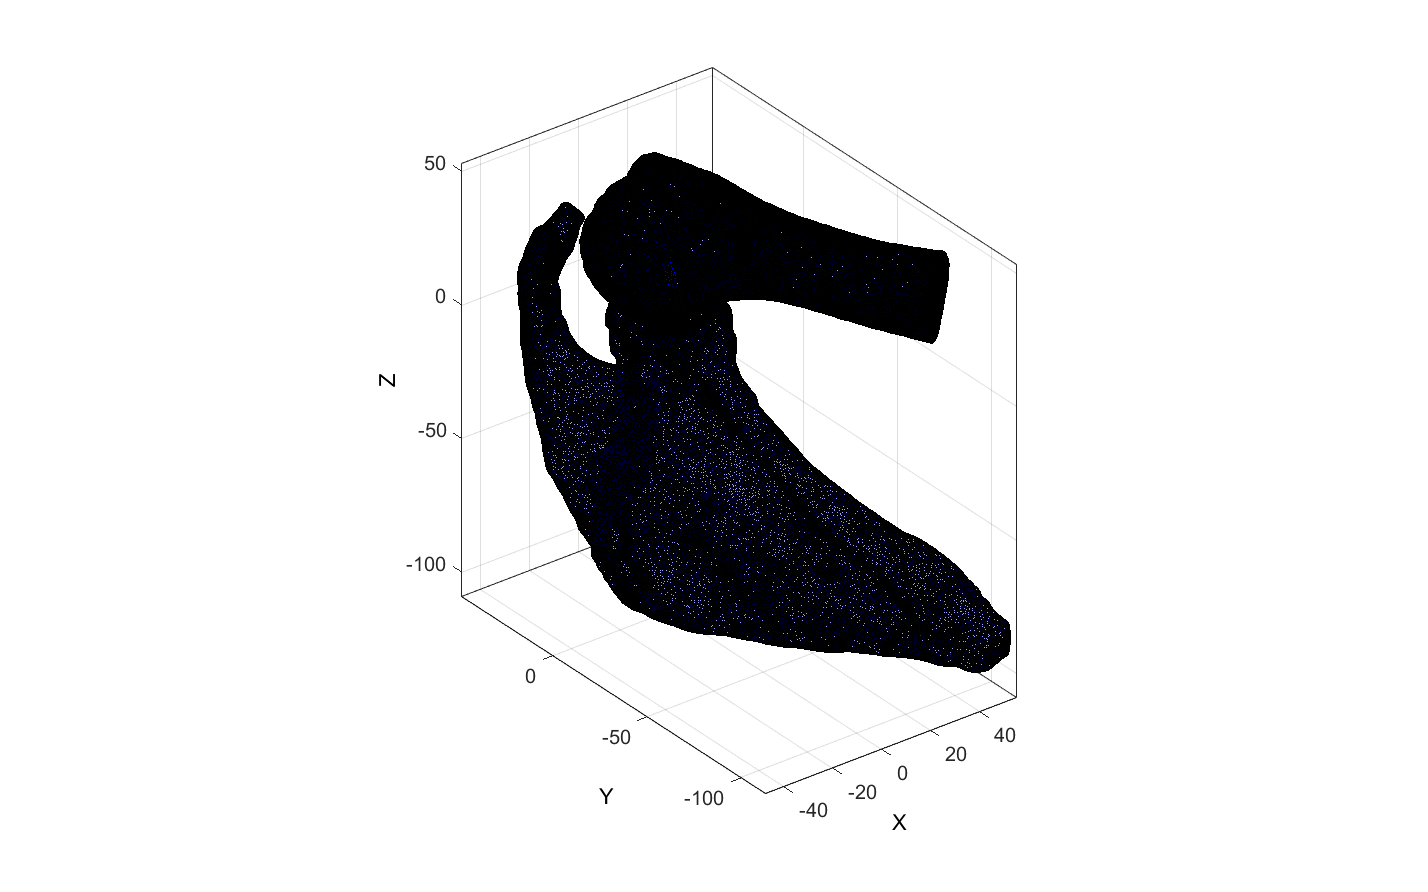

%Calculate the rotation between the glenoid plane vector and the worlds
%Z-axis vector
r = vrrotvec(planes.scapulaXYplane.normal,[0,0,1]);
%Get the rotation matrix for this alignment
m = vrrotvec2mat(r);

%Rotate and translate the points so they align at the origin and world XY
%axis. This also ensures that the other axes align with the other glenoid
%planes, however, they then need to be rotated 90 degrees around the Z-axis
%for these to align to the appropriate coordinate system.
%Set translation vector
transVec = (landmarks.deepGlenoid * m);
%Scapula vertices
scapulaV = (scapulaV * m) - transVec;
%Humerus vertices
humerusV = (humerusV * m) - transVec;
%Surface sphere vertices
surfaceV = (surfaceV * m) - transVec;
%Landmarks
fld = fieldnames(landmarks);
for ff = 1:length(fld)
    landmarks.(fld{ff}) = (landmarks.(fld{ff}) * m) - transVec;
end
clear ff

%Do the final 90 dgeree rotation around the Z axis
%Scapula vertices
scapulaV = (scapulaV * rotz(-90));
%Humerus vertices
humerusV = (humerusV * rotz(-90));
%Surface sphere vertices
surfaceV = (surfaceV * rotz(-90));
%Landmarks
for ff = 1:length(fld)
    landmarks.(fld{ff}) = (landmarks.(fld{ff}) * rotz(-90));
end
clear ff fld

%Visualise rotated data
cFigure;
gpatch(scapulaF,scapulaV,'b','k',0.2,1e-5);
hold on
gpatch(humerusF,humerusV,'b','k',0.2,1e-5);
axisGeom;
quiverVec([0,0,0],vecnormalize([1,0,0]),25,'r');
quiverVec([0,0,0],vecnormalize([0,1,0]),25,'g');
quiverVec([0,0,0],vecnormalize([0,0,1]),25,'b');

%Cleanup
clear r m

## Slice Up the Scapula

Use GIBBON's slicing tool to extract the glenoid face from the rest of the scapula. This will be sliced at a point 30mm back from the deep glenoid point along the normal of the plane fit to the glenoid surface. Prior to this though, so slicing along the X and Y axis directions is required to ensure extra bits of the scapula aren't included in the glenoid face.

Remove the back side of the scapula

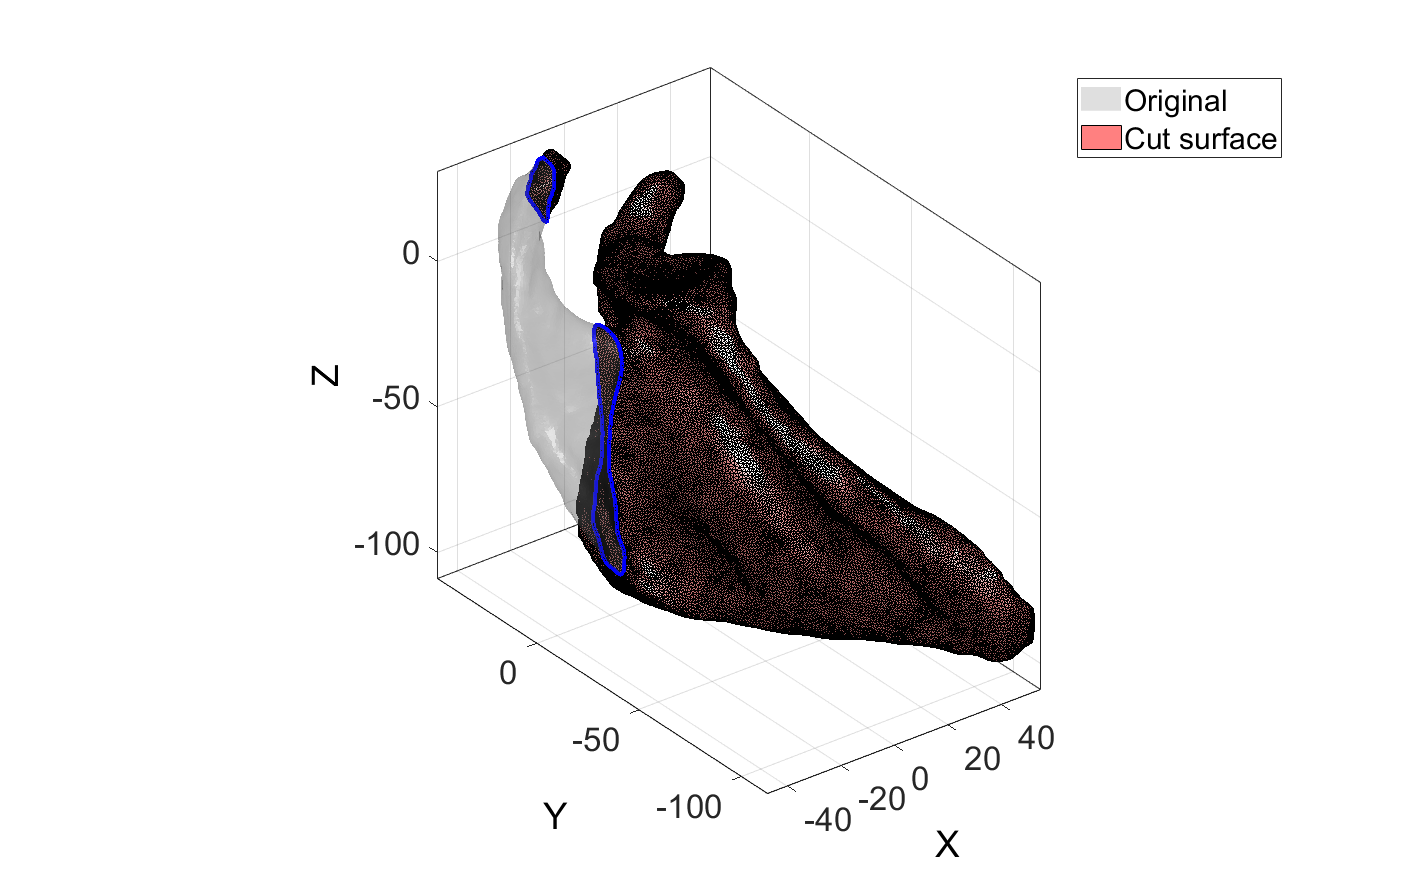

%Specify the snap tolerance
snapTolerance = mean(patchEdgeLengths(scapulaF,scapulaV))/100;

%Create the cutting plane by a normal vector
n = vecnormalize([-1 0 0]); %Normal direction to plane

%Specify the point on the plane (17mm back from the glenoid centre)
P = [-17,0,0];

%Slicing the surface (note 3rd color data output is supressed)
[scapulaF_slice,scapulaV_slice,~,logicSide,scapulaE_slice] = ...
    triSurfSlice(scapulaF,scapulaV,[],P,n,snapTolerance);

%Keep only part below the plane and clean up
[scapulaF_slice,scapulaV_slice,indFix] = patchCleanUnused(scapulaF_slice(logicSide,:),scapulaV_slice);
scapulaE_slice = indFix(scapulaE_slice);

%Visualise cut
cFigure; hold on;
hp1 = gpatch(scapulaF,scapulaV,'kw','none',0.25);
hp2 = gpatch(scapulaF_slice,scapulaV_slice,'rw','k',1);
gpatch(scapulaE_slice,scapulaV_slice,'none','b',1,3);
legend([hp1 hp2],{'Original','Cut surface'})
axisGeom; axis manual; camlight headligth;
colormap gjet;
set(gca,'FontSize',fontSize)

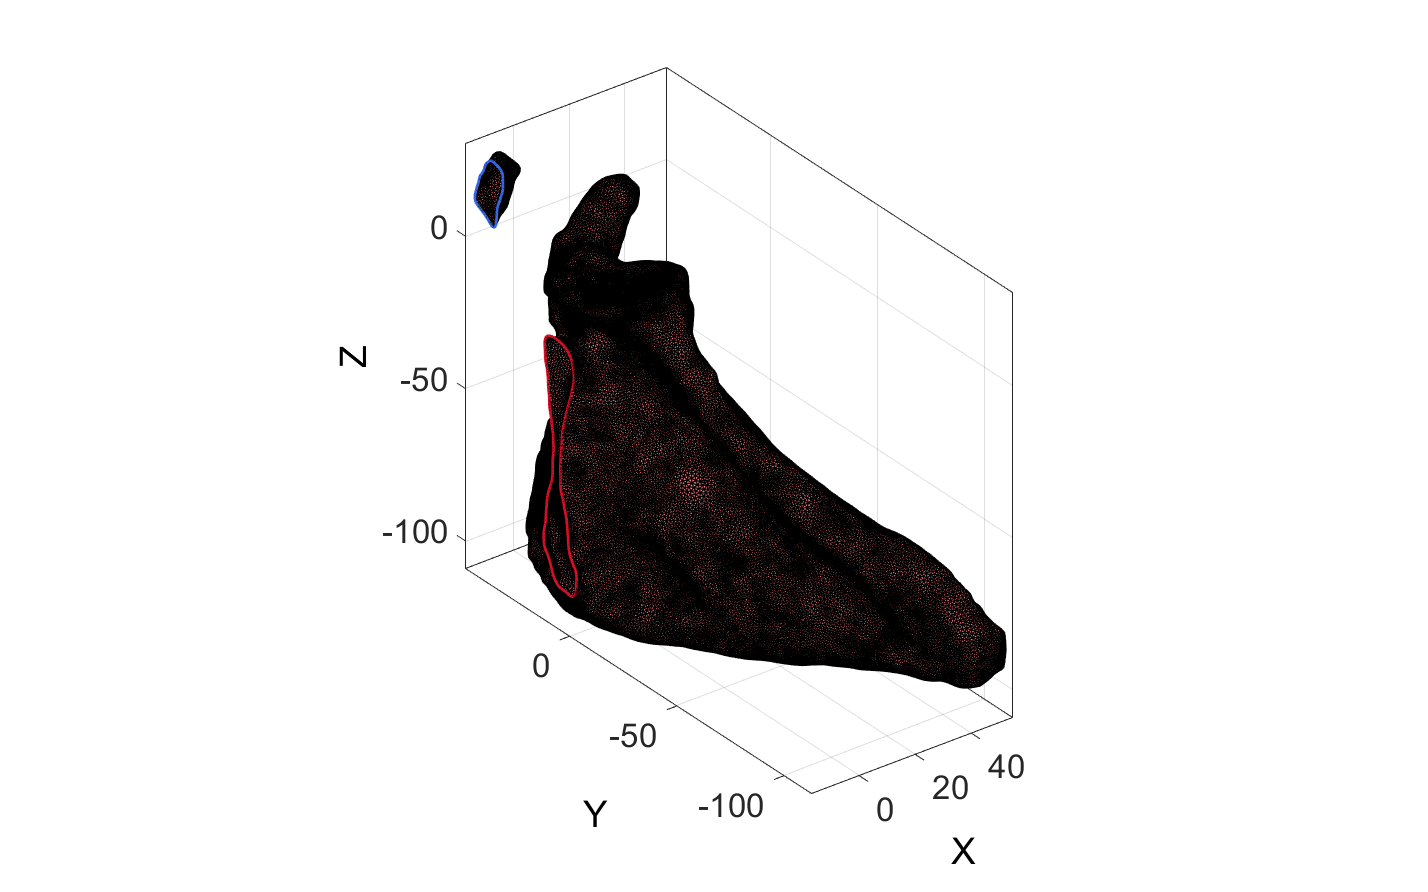


%Fix holes

%Get the indices for the boundary curves
Eb = patchBoundary(scapulaF_slice,scapulaV_slice);

%Use grouping to separate the boundary sets
optionStruct.outputType = 'label';
G = tesgroup(Eb,optionStruct);

%Visualise separate boundaries
cFigure; hold on;
gpatch(scapulaF_slice,scapulaV_slice,'rw','k',1,1);
axisGeom(gca,fontSize);
plotColors=gjet(max(G(:)));
for q = 1:1:max(G(:))
    E_now = Eb(G==q,:);
    [indListNow] = edgeListToCurve(E_now);
    hp = plotV(scapulaV_slice(indListNow,:),'b-','LineWidth',2);
    hp.Color=plotColors(q,:);
end

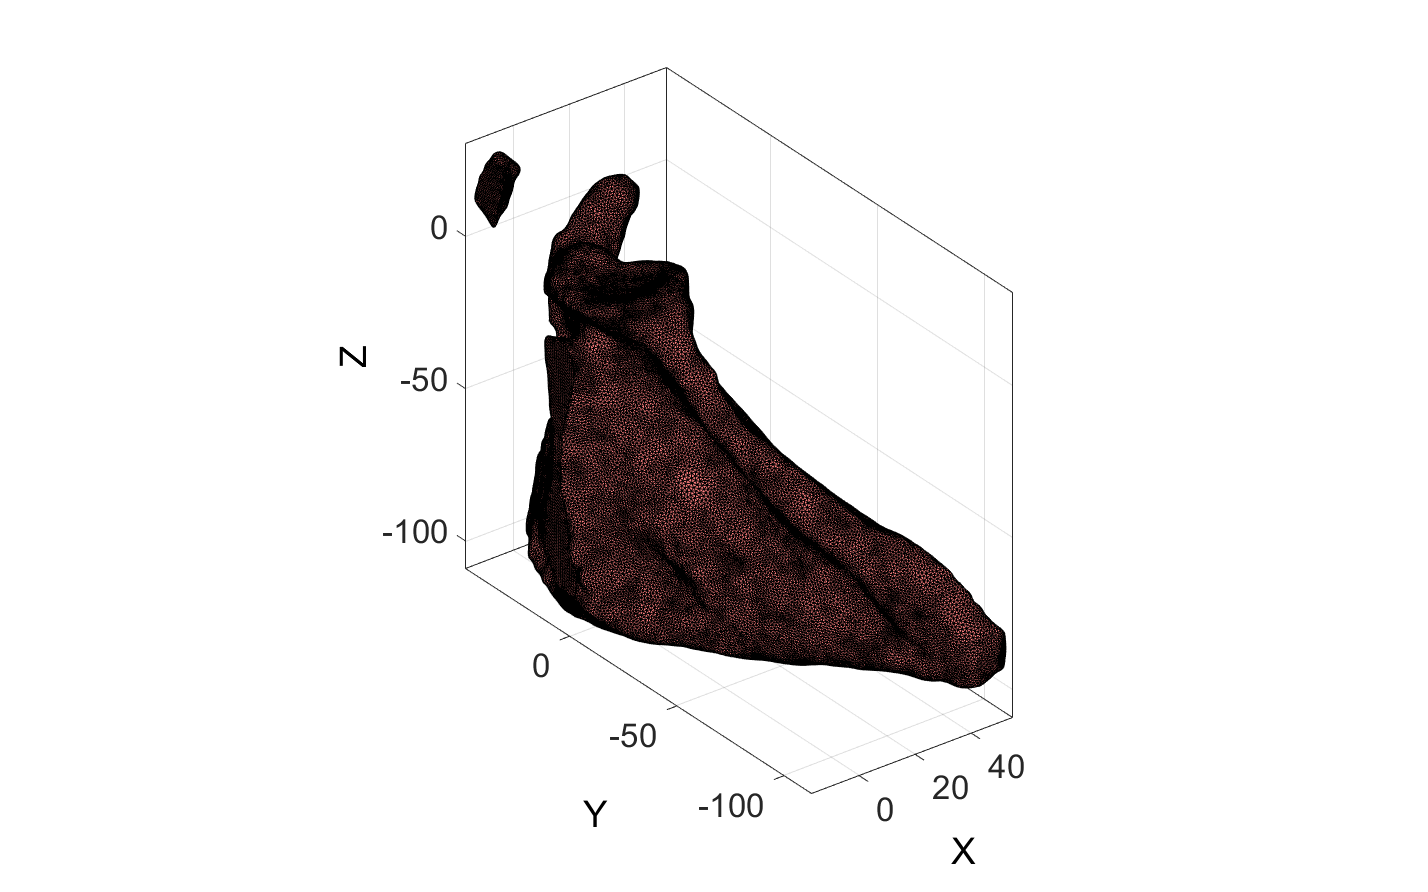


%Loop through and fill the holes
for q=1:1:max(G(:))
    %Get the current boundary as a curve
    E_now = Eb(G==q,:);
    [indListNow] = edgeListToCurve(E_now);
    %Remove the final point to make the curve discontinuous for meshing
    regionCurve = scapulaV_slice(indListNow,:);
    regionCell = {regionCurve(1:end-1,:)};
    %Fill the curve
    pointSpacing = 1.0; %samer as bone mesh
    resampleCurveOpt = 1; %option for resampling the curve
    interpMethod = 'linear'; %or 'natural'
    [fillF,fillV] = regionTriMesh3D(regionCell,pointSpacing,resampleCurveOpt,interpMethod);
    %Update and join the element sets
    [scapulaF_slice,scapulaV_slice] = joinElementSets({scapulaF_slice,fillF},{scapulaV_slice,fillV});
    %Cleanup
    clear E_now indListNow regionCurve regionCell fillF fillV
end

%Clean up new scapula object
[scapulaF_slice,scapulaV_slice] = mergeVertices(scapulaF_slice,scapulaV_slice);

%Visualise updated object
cFigure; hold on;
gpatch(scapulaF_slice,scapulaV_slice,'rw','k',1);
axisGeom; 
set(gca,'FontSize',fontSize)


%Cleanup
clear Eb G

Cut above the glenoid

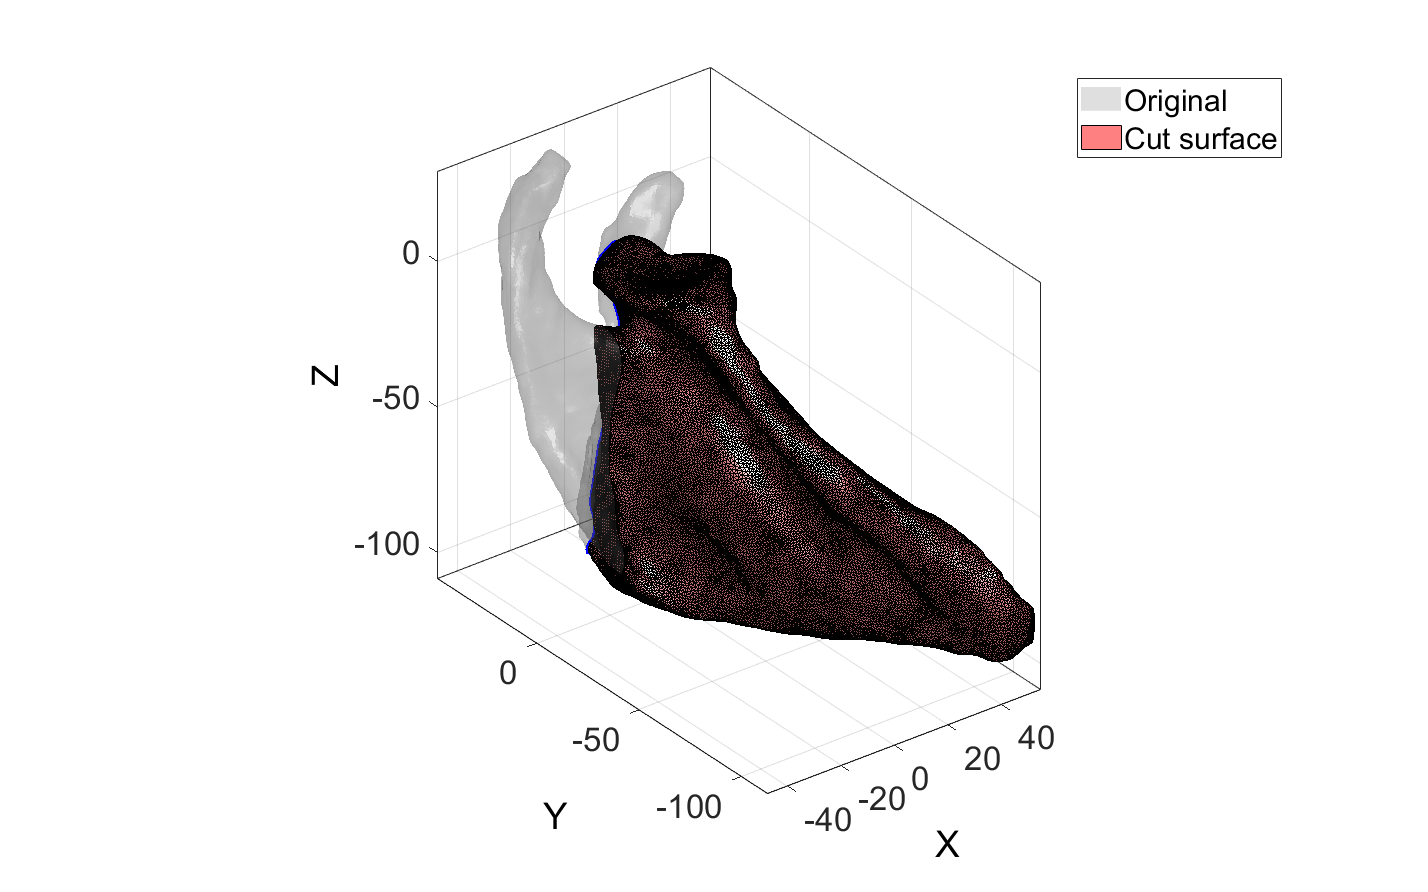

%Create the cutting plane by a normal vector
n = vecnormalize([0 1 0]); %Normal direction to plane

%Specify the point on the plane (25mm above the glenoid centre)
P = [0,25,0];

%Slicing the surface (note 3rd color data output is supressed)
[scapulaF_slice,scapulaV_slice,~,logicSide,scapulaE_slice] = ...
    triSurfSlice(scapulaF_slice,scapulaV_slice,[],P,n,snapTolerance);

%Keep only part below the plane and clean up
[scapulaF_slice,scapulaV_slice,indFix] = patchCleanUnused(scapulaF_slice(logicSide,:),scapulaV_slice);
scapulaE_slice = indFix(scapulaE_slice);

%Visualise cut
cFigure; hold on;
hp1 = gpatch(scapulaF,scapulaV,'kw','none',0.25);
hp2 = gpatch(scapulaF_slice,scapulaV_slice,'rw','k',1);
gpatch(scapulaE_slice,scapulaV_slice,'none','b',1,3);
legend([hp1 hp2],{'Original','Cut surface'})
axisGeom; axis manual; camlight headligth;
colormap gjet;
set(gca,'FontSize',fontSize)

***TODO: figure out why this cut gives an error when trying to fill. The solution for now is to push on with the cutting and see whether the whole back side can be filled together. The issue with this is if we wanted to just set the very back side as a boundary condition, it is not completely captured here***

Cut the back of the surface

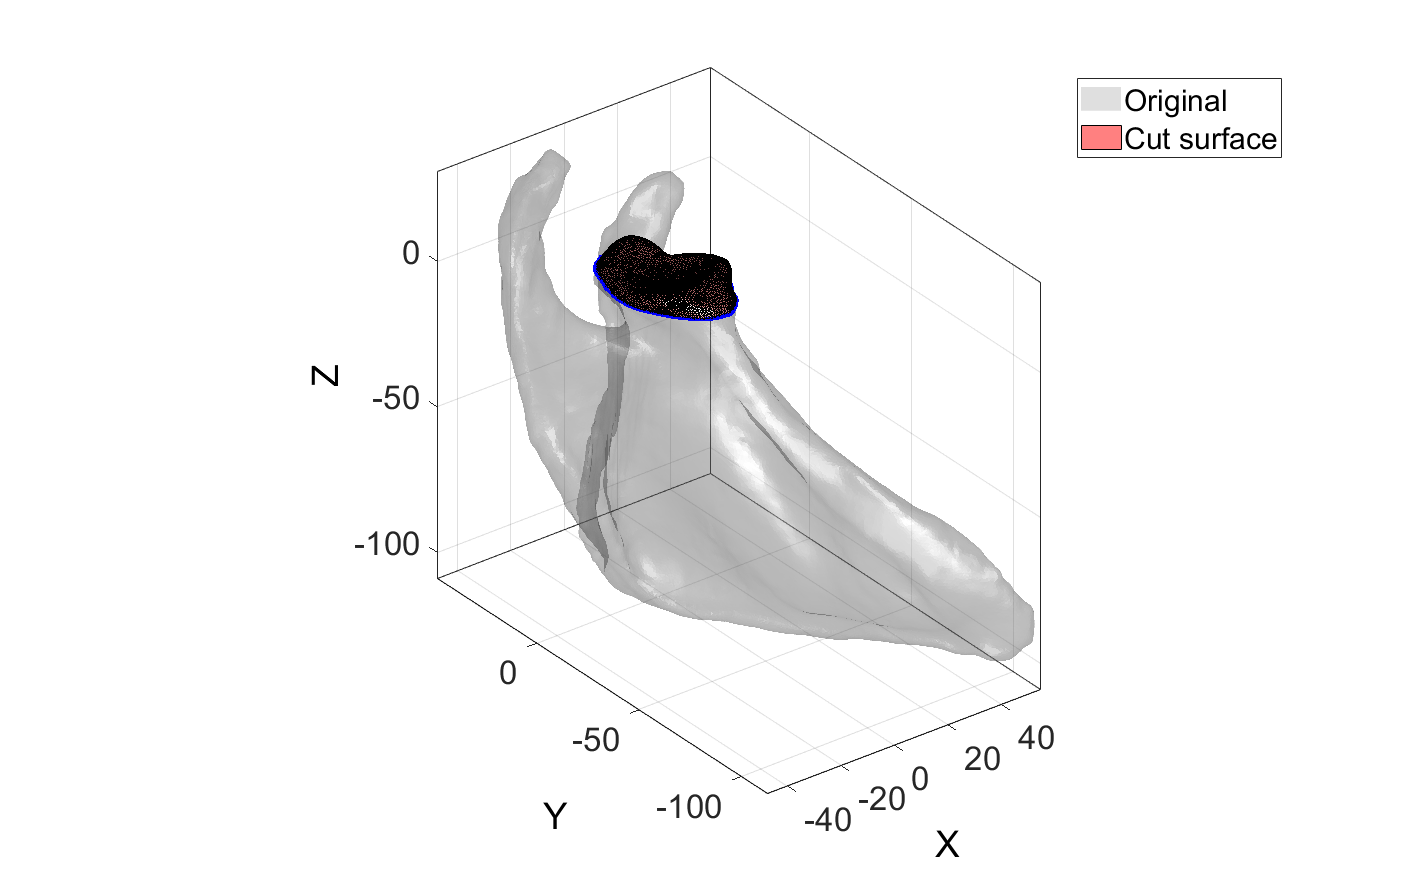

%Create the cutting plane by a normal vector
n = vecnormalize([0 0 -1]); %Normal direction to plane

%Specify the point on the plane (30mm back from the glenoid face)
P = [0,0,-3];

%Slicing the surface (note 3rd color data output is supressed)
[scapulaF_slice,scapulaV_slice,~,logicSide,scapulaE_slice] = ...
    triSurfSlice(scapulaF_slice,scapulaV_slice,[],P,n,snapTolerance);

%Keep only part below the plane and clean up
[scapulaF_slice,scapulaV_slice,indFix] = patchCleanUnused(scapulaF_slice(logicSide,:),scapulaV_slice);
scapulaE_slice = indFix(scapulaE_slice);

%Visualise kept piece
cFigure; hold on;
hp1 = gpatch(scapulaF,scapulaV,'kw','none',0.25);
hp2 = gpatch(scapulaF_slice,scapulaV_slice,'rw','k',1);
gpatch(scapulaE_slice,scapulaV_slice,'none','b',1,3);
legend([hp1 hp2],{'Original','Cut surface'})
axisGeom; axis manual; camlight headligth;
colormap gjet;
set(gca,'FontSize',fontSize);

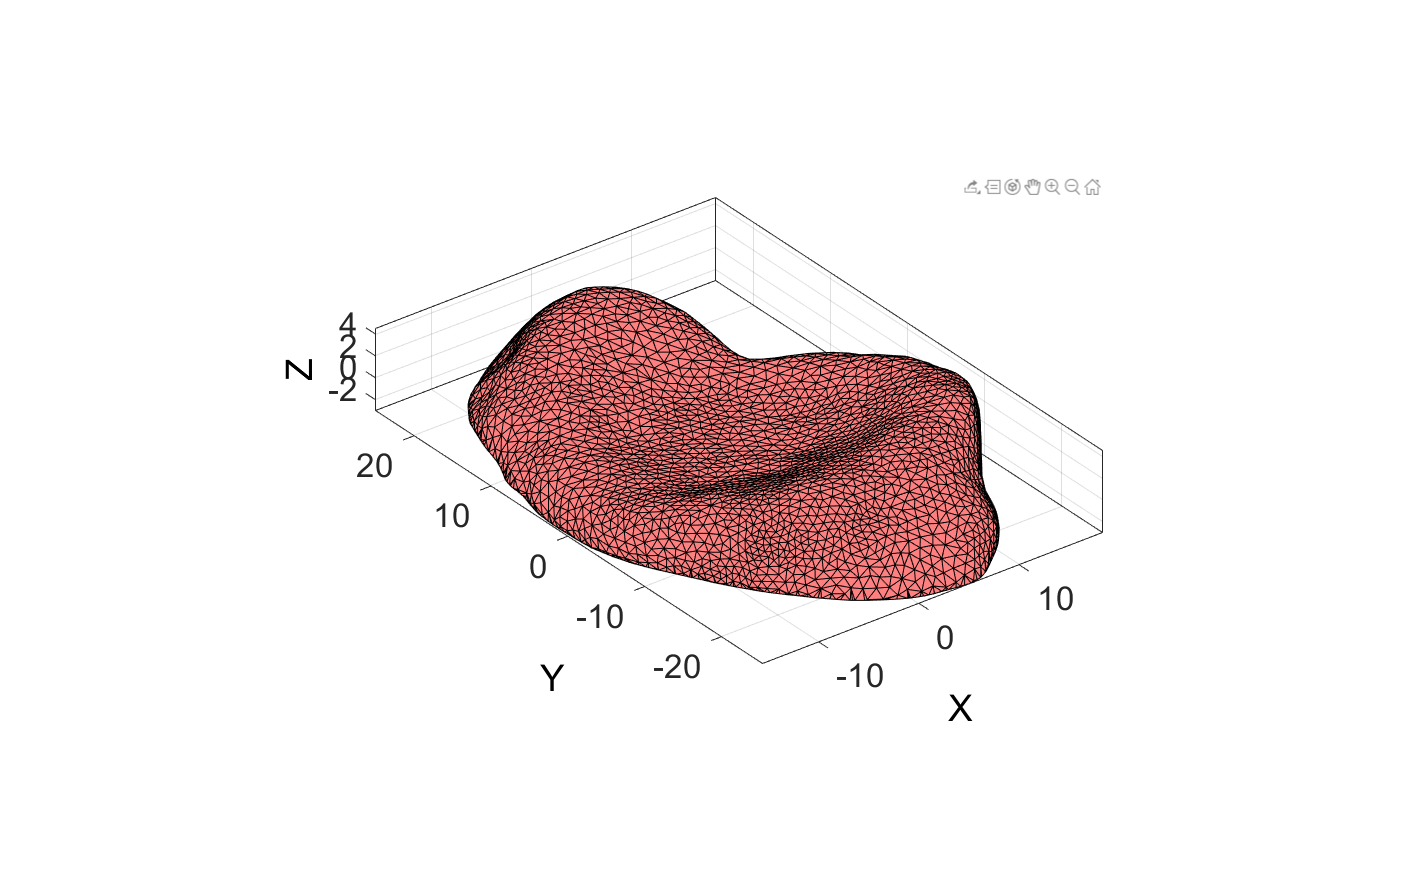


%Fix holes

%This section only has one top boundary so can be more easily fixed

%Get the indices for the boundary curves
Eb = patchBoundary(scapulaF_slice,scapulaV_slice);

%Get the boundary as a curve
[indListNow] = edgeListToCurve(Eb);
%Remove the final point to make the curve discontinuous for meshing
regionCurve = scapulaV_slice(indListNow,:);
regionCell = {regionCurve(1:end-1,:)};
%Fill the curve
pointSpacing = 1.0; %samer as bone mesh
resampleCurveOpt = 1; %option for resampling the curve
interpMethod = 'linear'; %or 'natural'
[fillF,fillV] = regionTriMesh3D(regionCell,pointSpacing,resampleCurveOpt,interpMethod);
%Update and join the element sets
[scapulaF_slice,scapulaV_slice] = joinElementSets({scapulaF_slice,fillF},{scapulaV_slice,fillV});
%Cleanup
clear E_now indListNow regionCurve regionCell fillF fillV

%Clean up new scapula object
[scapulaF_slice,scapulaV_slice] = mergeVertices(scapulaF_slice,scapulaV_slice);

%Visualise updated object
cFigure; hold on;
gpatch(scapulaF_slice,scapulaV_slice,'rw','k',1);
axisGeom; 
set(gca,'FontSize',fontSize)

***TODO: There may still be some sharp triangle edges that could cause issues with volume meshing later.***

## Use the Glenoid Surface to Create Cartilage

In 3matic, faces approximating the glenoid surface were selected and exported as their own surface. We can project these in a way that creates cartilage.

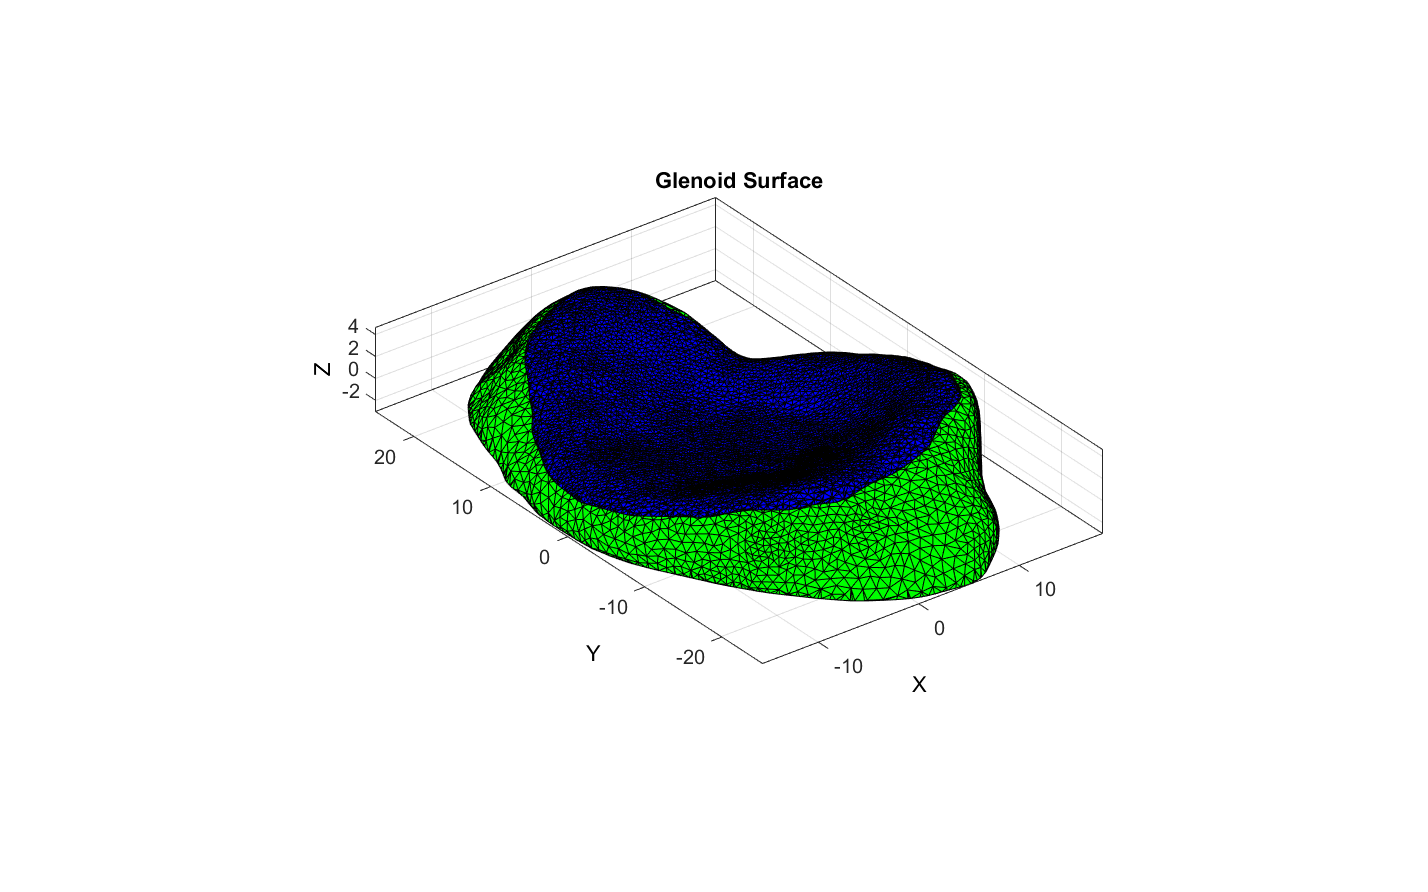

%Set a new glenoid vairable to call easier
glenoidV = scapulaV_slice;
glenoidF = scapulaF_slice;
glenoidE = scapulaE_slice;

%Nudge the coordinates of the surface a tiny amount so it sits just above
%the glenoid
surfaceV(:,3) = surfaceV(:,3) + 0.1;

%Visualise the cut glenoid surface and the approximation of the face
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot approximated surface
gpatch(surfaceF,surfaceV,'b','k',1);

We can get the edge points of the glenoid surface as a boundary curve and use this in the loft sweep function.

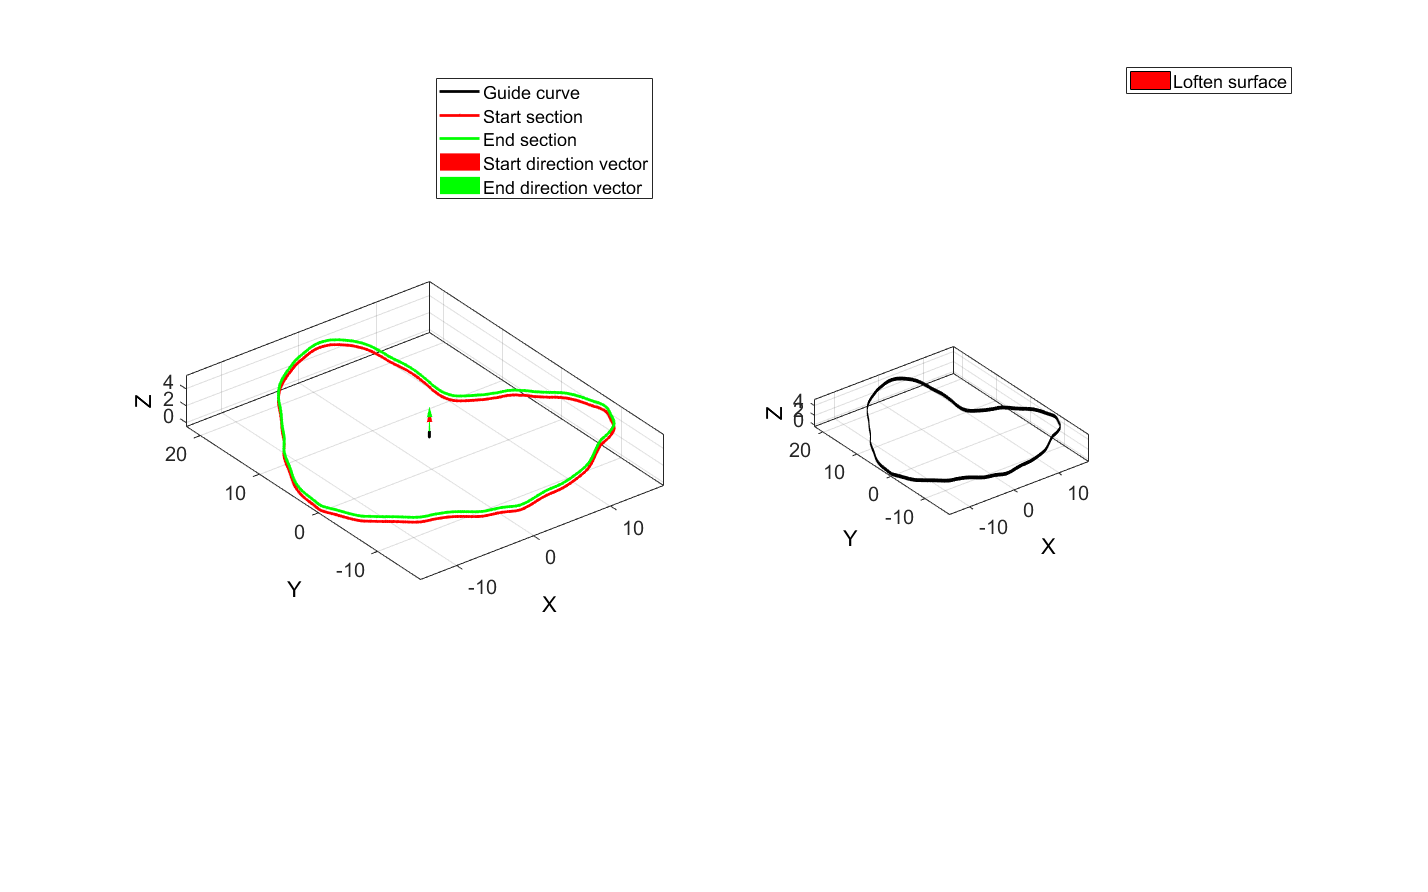

%Get the boundary points
cartilageBaseEb = patchBoundary(surfaceF,surfaceV);
cartilageBaseBC = edgeListToCurve(cartilageBaseEb);
cartilageBaseBC = cartilageBaseBC(1:end-1)'; %Start=End for closed curve so remove double entry

%Set start loft
startLoft = surfaceV(cartilageBaseBC,:);

%Create the second sketch by adding the z-translation value based on the
%max cartilage thickness
endLoft = [startLoft(:,1),startLoft(:,2),startLoft(:,3)+maxCartilageThickness];

%Create a guide curve (some default parameters)
%Should just be a straight line really...
numStepsCurve = round(maxCartilageThickness*10); %Number of steps for the curve
p1 = mean(startLoft,1); %First point
n1 = [0,0,1]; %First direction vector; z direction
p2 = mean(endLoft,1); %End point
n2 = [0,0,1]; %End direction vector; z direction
csapsSmoothPar = 1; %Cubic smoothening spline smoothening parameter
f = 0.05; %Extent of tangential nature to boundary curves, surface will remain approximately orthogonal to input curves for f*distance between curves
[Vg] = sweepCurveSmooth(p1,p2,n1,n2,numStepsCurve,csapsSmoothPar,f);

%Create the loft feature
[cartilageOuterF,cartilageOuterV] = sweepLoft(startLoft,endLoft,n1,n2,Vg);

%Visualise the loft feature
cFigure;
subplot(1,2,1);
hold on;
h(1)=plotV(Vg,'k.-','LineWidth',2);
h(2)=plotV(startLoft,'r.-','LineWidth',2);
h(3)=plotV(endLoft,'g.-','LineWidth',2);
h(4)=quiverVec(p1,n1,3,'r');
h(5)=quiverVec(p2,n2,3,'g');
legend(h,{'Guide curve','Start section','End section','Start direction vector','End direction vector'});
axisGeom;

subplot(1,2,2); hold on;
h = gpatch(cartilageOuterF,cartilageOuterV,'r','k',1);
axisGeom;
legend(h,{'Loften surface'});
camlight headlight

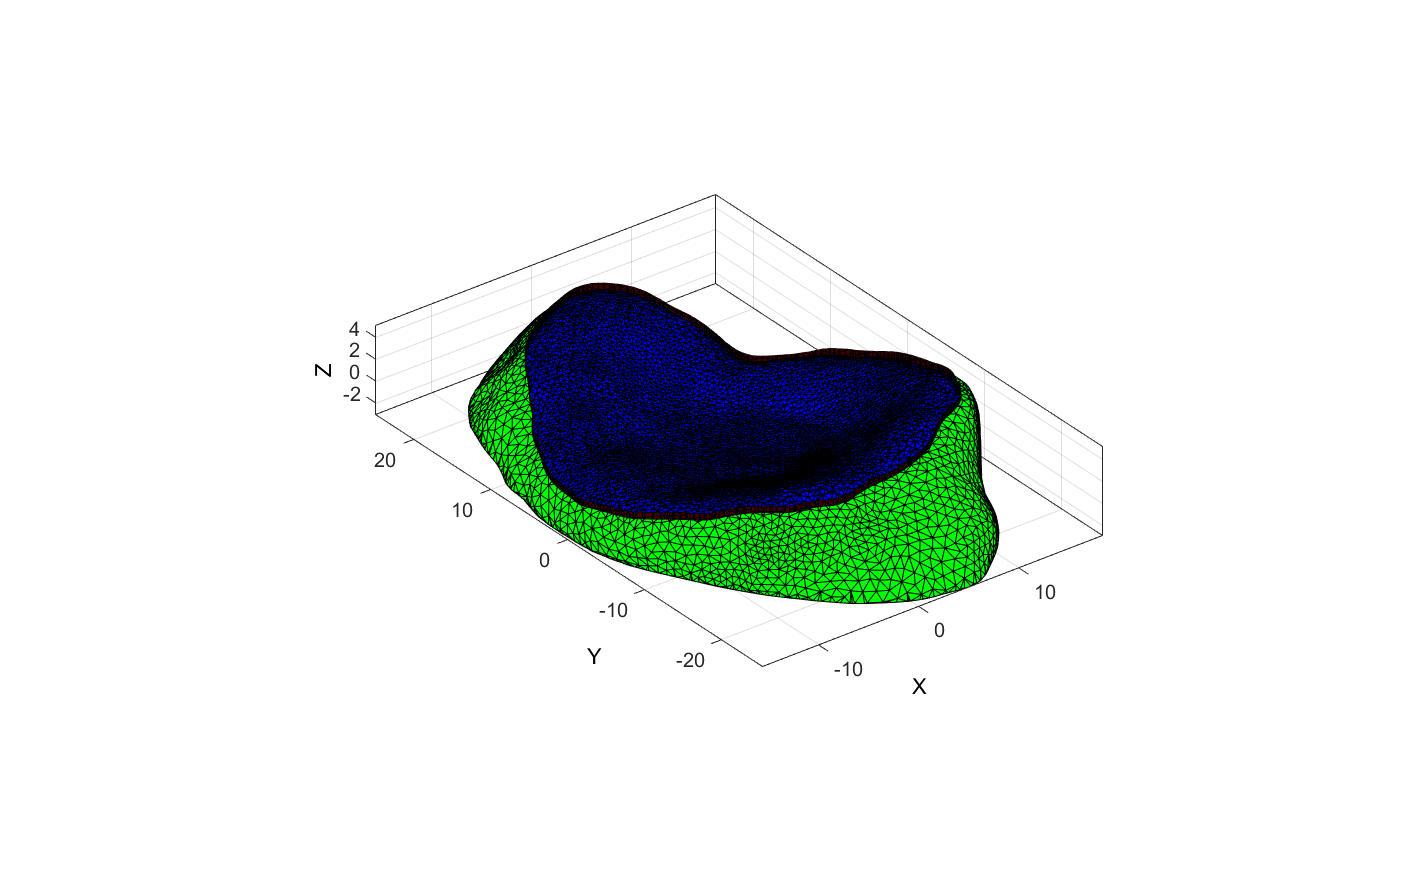


%Visualise the cartilage loft with the glenoid
cFigure; hold on;
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot cartilgae loft
gpatch(surfaceF,surfaceV,'b','k',1);
%Plot the cartilage base
gpatch(cartilageOuterF,cartilageOuterV,'r','k',1);

The next step is to set a top border for the cartilage. We could use the region meshing functions from GIBBON, but the smoothness of the glenoid surface mesh probably means that we can just copy and translate this up by the cartilage thickness and it will probably fit nicely with the end loft.

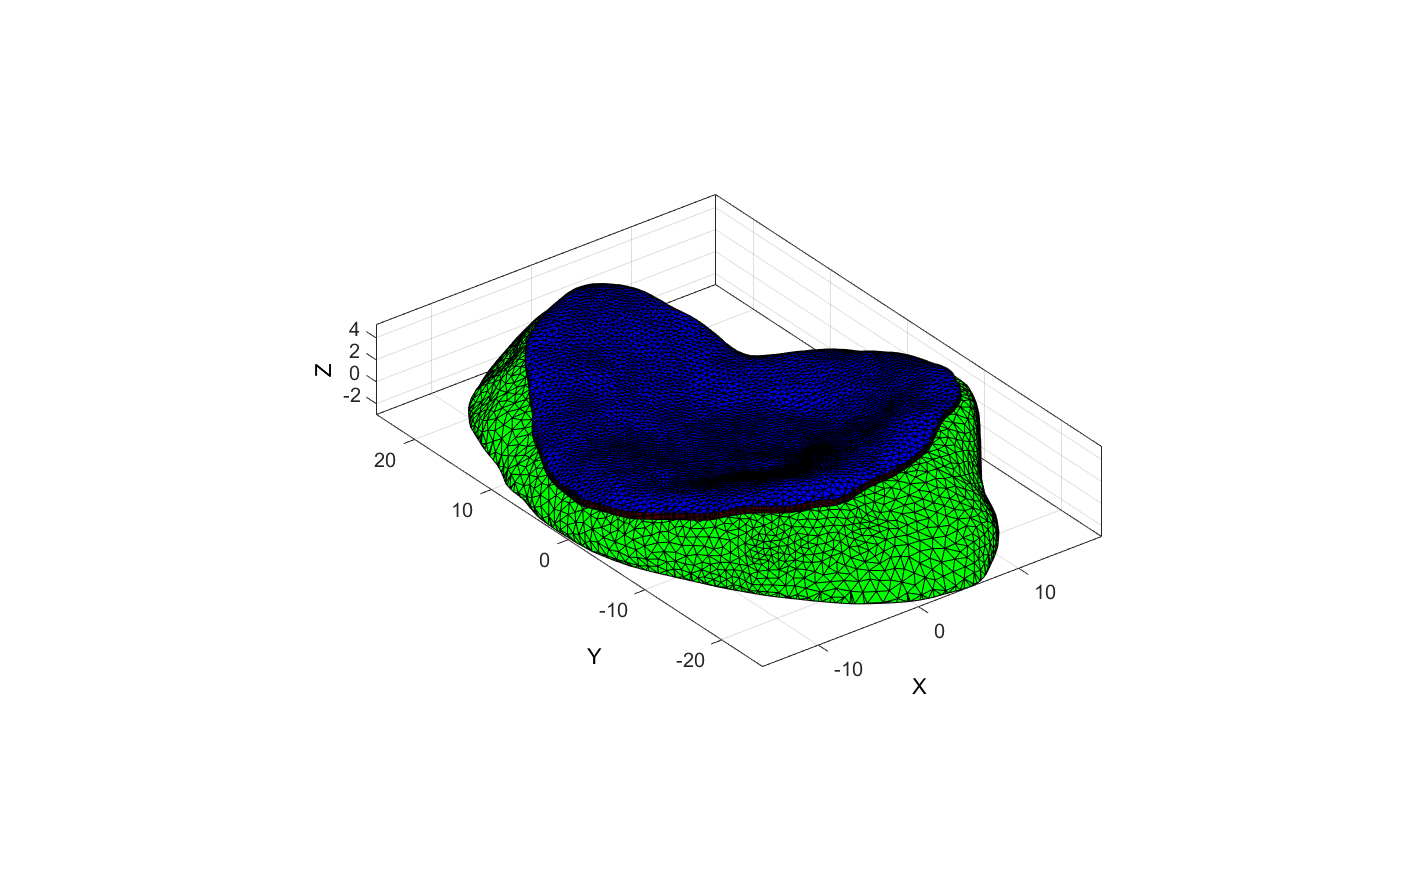

%Create copy of the glenoid surface
cartilageTopF = surfaceF;
cartilageTopV = surfaceV;

%Translate the z-coordiate of the vertices by the cartilage thickness
cartilageTopV(:,3) = cartilageTopV(:,3) + maxCartilageThickness;

%Visualise all parts of the cartilage together
cFigure; hold on;
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot cartilage
gpatch(surfaceF,surfaceV,'b','k',1);
gpatch(cartilageOuterF,cartilageOuterV,'r','k',1);
gpatch(cartilageTopF,cartilageTopV,'b','k',1);

The above method works nicely to fit the top of the cartilage. The glenoid surface could be smoother, which would result in the cartilage surface being smoother - which could be desirable for simulations. 

The top surface could be perturbed based on a linear function with respect to distance from the centre - whereby the closer it gets to the centre it is dropped down along the z-axis to emulate thinner cartilage towards the centre of the glenoid.

## Generate the Humeral Head Sphere

This step will generate an apprximation of the humeral head as a mesh based on the fitted sphere from 3matic.

***TODO: This just generates the humeral head rigid body, without considering the cartilage layer that we could use.***

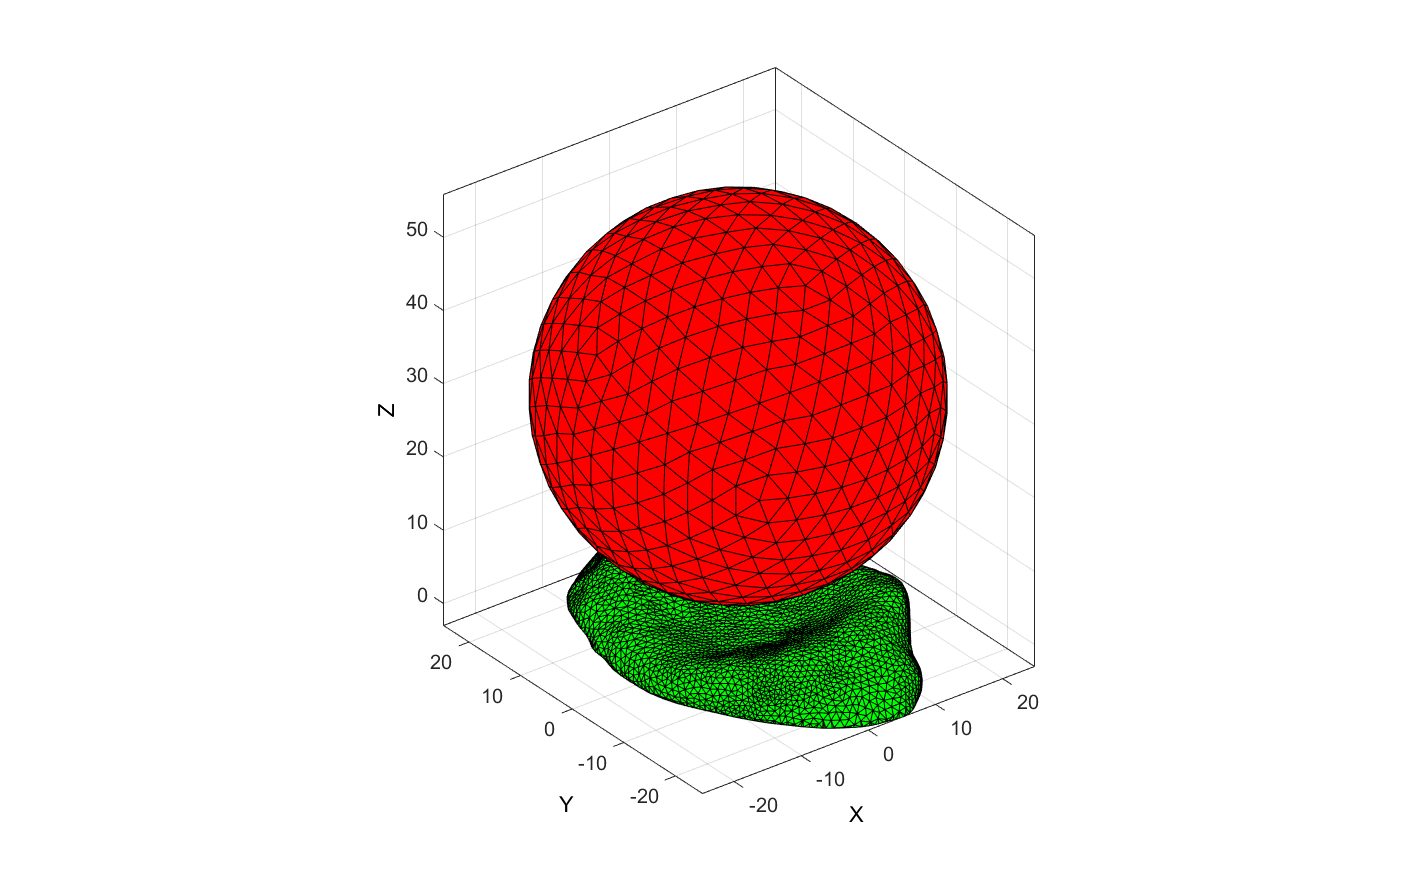

%Create a triangulated sphere model
numRefineStepsSphere = 3;
[humeralHeadE,humeralHeadV,~]=geoSphere(numRefineStepsSphere,humeralHeadRadius);
comHumeralHead = mean(humeralHeadV,1);

% % % %Offset the sphere in each direction based on the outputted humeral head
% % % %position
% % % humeralHeadV(:,1) = humeralHeadV(:,1) + landmarks.humeralHeadCentre(1);
% % % humeralHeadV(:,2) = humeralHeadV(:,2) + landmarks.humeralHeadCentre(2);
% % % humeralHeadV(:,3) = humeralHeadV(:,3) + landmarks.humeralHeadCentre(3);

%Offset humeral head by a specific z-displacement relative to the origin
humeralHeadV(:,3) = humeralHeadV(:,3) + 31;

%Visualise surfaces together
cFigure; hold on;
gpatch(glenoidF,glenoidV,'g','k',1);
gpatch(humeralHeadE,humeralHeadV,'r','k',1);
axisGeom;

## Fix the Cartilage Mesh Up

The cartilage mesh needs to be fixed in a couple of ways:

- The normals of the surface side likely need to be reversed outwards so that they go towards the glenoid.

- The mesh parts need to all be joined together

First, fix the normales

%Flip the surface faces so that the normals point towards the glenoid
surfaceF = fliplr(surfaceF);

Now combine all the cartilage parts together.

***TODO: could uniformly space mesh to clean up more if appropriate?***

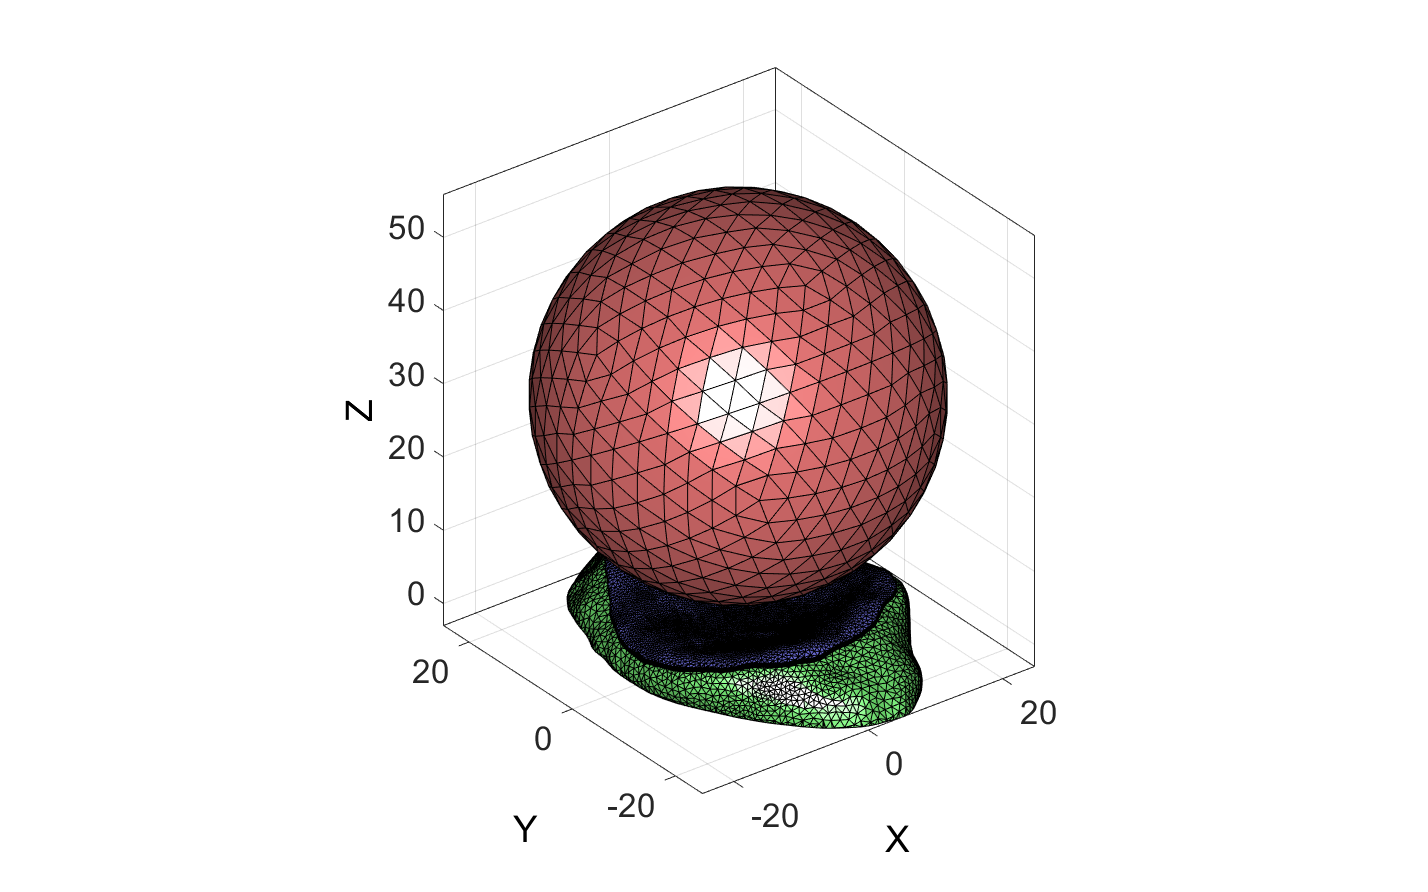

%Join element sets
%First need to convert outer mesh to triangles for consistency
[cartilageOuterF,cartilageOuterV] = quad2tri(cartilageOuterF,cartilageOuterV);
[cartilageF,cartilageV] = joinElementSets({surfaceF,cartilageOuterF,cartilageTopF},...
    {surfaceV,cartilageOuterV,cartilageTopV});


%Clean up new object
[cartilageF,cartilageV] = mergeVertices(cartilageF,cartilageV);

%Visualise all objects together
cFigure; hold on;
hp1 = gpatch(glenoidF,glenoidV,'gw');
hp2 = gpatch(cartilageF,cartilageV,'bw');
hp3 = gpatch(humeralHeadE,humeralHeadV,'rw');
axisGeom; axis manual; camlight headligth;
set(gca,'FontSize',fontSize);

## Export Some Objects to Play Around in FEBio

Export the glenoid and cartilage STL's to have a bit of a manual test in FEBio

%Export STLs

%Glenoid
stlStruct.solidNames={'glenoid'}; %names of parts
stlStruct.solidVertices = {glenoidV}; %Vertices
stlStruct.solidFaces={glenoidF}; %Faces
stlStruct.solidNormals={[]}; %Face normals (optional)
export_STL_txt('processedGlenoid.stl',stlStruct);
clear stlStruct

%Cartilage
stlStruct.solidNames={'cartilage'}; %names of parts
stlStruct.solidVertices = {cartilageV}; %Vertices
stlStruct.solidFaces={cartilageF}; %Faces
stlStruct.solidNormals={[]}; %Face normals (optional)
export_STL_txt('processedCartilage.stl',stlStruct);
clear stlStruct

***TODO: run through a similar FEBio example from the GIBBON toolbox to test out these materials. This will require generating meshes for the glenoid and cartilage.***

***TODO:***

- ***The normals of the glenoid surface of the cartilage likely need to be inverted so that contact between this and the glenoid face can be achieved (i.e. rigid contact)***

- ***The humeral head sphere needs to be created and meshed, and a cartilage layer added to this (i.e. potentially consistent thickness, travelling around a certain proportion of the sphere).***

- ***Once all structural issues are fixed, a potential FEA protocol can be tested: rigidly fix the glenoid body and attach the cartilage as an elastic material to this; attach the humeral cartilage to the rigid body humeral sphere; apply rigid body forces to the humeral sphere to collide and translate along the glenoid cartilage.***